A  Explore the data and comment on your findings.

**Descriptive Statistics**

clc, clf, clear

craneA = [140 140 112 90 32 154 359 207 61 39 40];
craneB = [69 14 38 94 46 36 84 106 269 445 42 108 244 92 148 303 24 328 207 260 132 56];
craneC = [39 135 57 31 190 90 293 151 26 77 82 156 328 92 138 47 45];

% Calculate number of samples
nA = length(craneA);
nB = length(craneB);
nC = length(craneC);

% Calculate mean of samples
avgA = mean(craneA);
avgB = mean(craneB);
avgC = mean(craneC);

% Calculate median of samples
mA = median(craneA);
mB = median(craneB);
mC = median(craneC);

% Calculate minimum of samples
minA = min(craneA);
minB = min(craneB);
minC = min(craneC);

% Calculate maximum of samples
maxA = max(craneA);
maxB = max(craneB);
maxC = max(craneC);

% Calculate range of samples
rA = maxA - minA;
rB = maxB - minB;
rC = maxC - minC;

% Calculate variance of samples
varA = var(craneA);
varB = var(craneB);
varC = var(craneC);

% Calculate standard deviation of samples
stdA = std(craneA);
stdB = std(craneB);
stdC = std(craneC);

%  Calcuate CV
cvA = stdA / avgA;
cvB = stdB / avgB;
cvC = stdC / avgC;

% Calculate IQR
iqrA = iqr(craneA);
iqrB = iqr(craneB);
iqrC = iqr(craneC);

% Quartiles
Q1A = prctile(craneA, 25); Q3A = prctile(craneA, 75);
Q1B = prctile(craneB, 25); Q3B = prctile(craneB, 75);
Q1C = prctile(craneC, 25); Q3C = prctile(craneC, 75);

% Calculate outlier
outliersA = craneA(craneA > (Q3A + 1.5 * iqrA) | craneA < (Q1A - 1.5 * iqrA));
outliersB = craneB(craneB > (Q3B + 1.5 * iqrB) | craneB < (Q1B - 1.5 * iqrB));
outliersC = craneC(craneC > (Q3C + 1.5 * iqrC) | craneC < (Q1C - 1.5 * iqrC));

% Display results as table
names = {'Crane 14'; 'Crane 15'; 'Crane 16'};
n = [nA; nB; nC];
mean = [avgA; avgB; avgC];
median = [mA; mB; mC];
min = [minA; minB; minC];
max = [maxA; maxB; maxC];
range = [rA; rB; rC];
variance = [varA; varB; varC];
std = [stdA; stdB; stdC];
IQR = [iqrA; iqrB; iqrC];
outliers = {outliersA; outliersB; outliersC};
cv = [cvA; cvB; cvC];

T = table(n, mean, median, min, max, range, variance, std, cv, IQR, outliers,...
    'RowNames', names);

% Display table title
disp("Summary Statistics for Cranes")

Summary Statistics for Cranes


disp(T)

                n      mean     median    min    max    range    variance     std        cv        IQR        outliers  
                __    ______    ______    ___    ___    _____    ________    ______    _______    ______    ____________

    Crane 14    11    124.91     112      32     359     327      9153.1     95.672    0.76593    105.25    {[     359]}
    Crane 15    22    142.95     100      14     445     431       13907     117.93    0.82493       198    {1×0 double}
    Crane 16    17    116.29      90      26     328     302      7742.7     87.993    0.7

**初步分析**

样本量：crane 15 拥有最多的样本数量 n = 22, crane 14（n=11）和 crane 16（n=17）相比，crane 15 的观察时间更长，通常来说其统计数据更加稳健。

集中趋势（ mean median)：

- crane 15 故障间隔时间最长， crane 16 故障间隔时间最短

- crane 14 中位数最大，其次是 crane 15, crane 16 最小

- 3个 crane median < mean , 表明数据可能收到outliner影响呈现右偏 right - skewed，crane 15 中最大间隔 445 可能拉高了平均值；crane 14 平均值（124.91）和中位数（112）更接近，表明其分布与其他crane相比更加对称

Variability  Spread

- crane 15 的 variability (CV ≈ 82%)，range（431）和标准差(117.93) 均最大。这意味crane 15 的测量值分布最分散。与平均值的差异较大，这可能是由于其最大值（445）过大造成的。

- crane 14 和 crane 16 的variability非常相似。

- 三台起重机均表现出较高的变异性，表明3个crane它们的运行状态不稳定。

Outliner: 

- The result indicates that the 3 samples may not behave consistently, where there are outliers exist in sample crane 14 and sample crane 16. 

- Although the calculation show no outlier exists in crane 15 sample, the data suggests that crane 15 sample data heavily spreaded. This may because the sample is highly skewed.

**Data visualization**

**Boxplot**

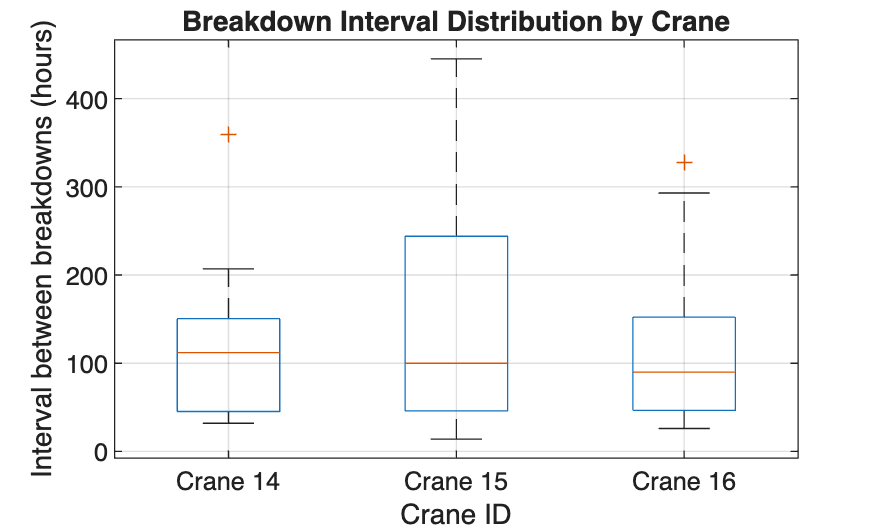

%% Combine data
all_data = [craneA'; craneB'; craneC'];
group_labels = [repmat({'Crane 14'}, length(craneA), 1);
           repmat({'Crane 15'}, length(craneB), 1);
           repmat({'Crane 16'}, length(craneC), 1)];

%% Create grouped box plot
figure;
boxplot(all_data, group_labels,'Labels', {'Crane 14', 'Crane 15', 'Crane 16'});
xlabel('Crane ID')
ylabel('Interval between breakdowns (hours)')
title('Breakdown Interval Distribution by Crane')
grid on;

**中位线：表明 50% **的故障发生时间在此值之下，Crane 14 在大多数情况下（50%）能运行更久才发生故障，其实际可靠性相对最好，而我们计算的平均值最高的是 Crane 15 ，这表明平均值受到 Crane 15 的极端高值影响较大。

变异性：（IQR）

Crane 15 : 箱子最长（从约 50 到 250）。Q3 ~ Q1最长（从 0 到约 450），因而故障间隔时间波动性最大，最难预测。它可能运行很短时间（接近 0），也可能运行极长时间（445）。

Crane 14 和 Crane 16 : 箱子和Q3~Q1的长度相对较短且接近，它们的故障时间间隔变异性较低，相对更容易预测。

最小值：crane 15 的最小值最小，说明维修后再次发生故障的风险较大， 同时 crane 15 也是可能运行时间最长的设备

**Histogram**

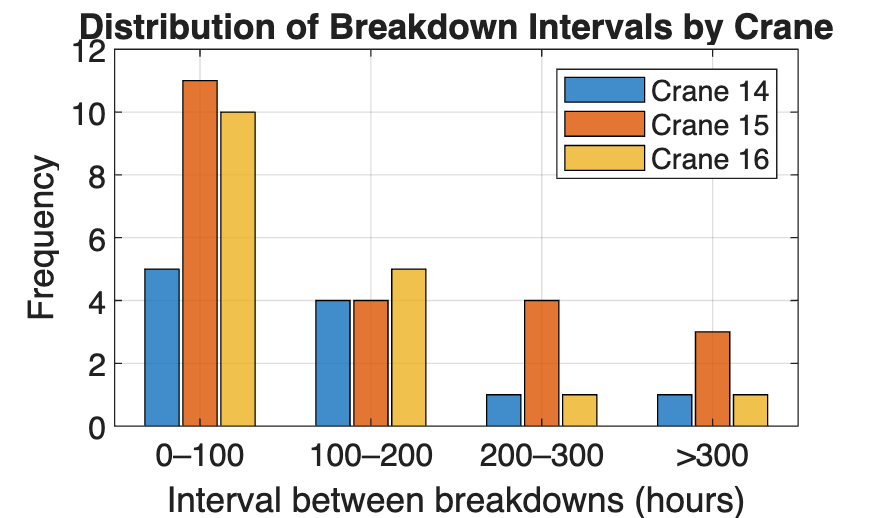

% === 设置参数 ===
bin_edges = [0 100 200 300 Inf];     % 分组区间
bin_labels = {'0–100','100–200','200–300','>300'};  % X轴标签
colors = lines(3);                   % 三种颜色

% === 计算频数 ===
[countA, ~] = histcounts(craneA, bin_edges);
[countB, ~] = histcounts(craneB, bin_edges);
[countC, ~] = histcounts(craneC, bin_edges);

% 计算每个bar中心点（显示位置）
binCenters = 1:length(bin_labels);

% 合并频数
counts = [countA(:), countB(:), countC(:)];

% === 绘图 ===
figure('Color','w','Position',[200 200 850 500]);
b = bar(binCenters, counts, 'grouped', 'BarWidth', 0.9);  % 柱宽略大一点
for i = 1:3
    b(i).FaceColor = colors(i,:);
    b(i).EdgeColor = 'k';
    b(i).FaceAlpha = 0.8;
end

% === 标签与图例 ===
set(gca, 'XTick', binCenters, 'XTickLabel', bin_labels, 'FontSize', 12);
xlabel('Interval between breakdowns (hours)');
ylabel('Frequency');
title('Distribution of Breakdown Intervals by Crane');
legend({'Crane 14','Crane 15','Crane 16'}, 'Location', 'northeast');
grid on;

**整体：**整个分布是强烈右偏（Right-Skewed）的，即条形图最高的峰值集中在左侧的低值区域（0-150 ），然后频率迅速下降，尾巴向右侧延伸

说明大部分故障是运行相对较短的时间后发生的，说明故障可能不是由于运行老化（老化应该是运行较长时间后出现故障问题），而是维护/操作/零件质量有关

0 到 100 小时：

-  26 次发生在 0 到 100 小时之间

- crane 15 和 16 次数较多，分别为11次和10次

- crane 14 发生5次

- 说明crane 15 和 16 故障后复发风险高

100 到 300 小时：

- 19 次 = 5 (14) + 8 (15) + 6 (16)

- 故障发生较为分散，没有明显区分，存在一定随机性

300 到 400 小时：

- 5次 = 1（14） + 3（15） + 1（16）

- crane 15 比 14 和16 有更长无故障运行时间，证明长时间运行的潜力存在

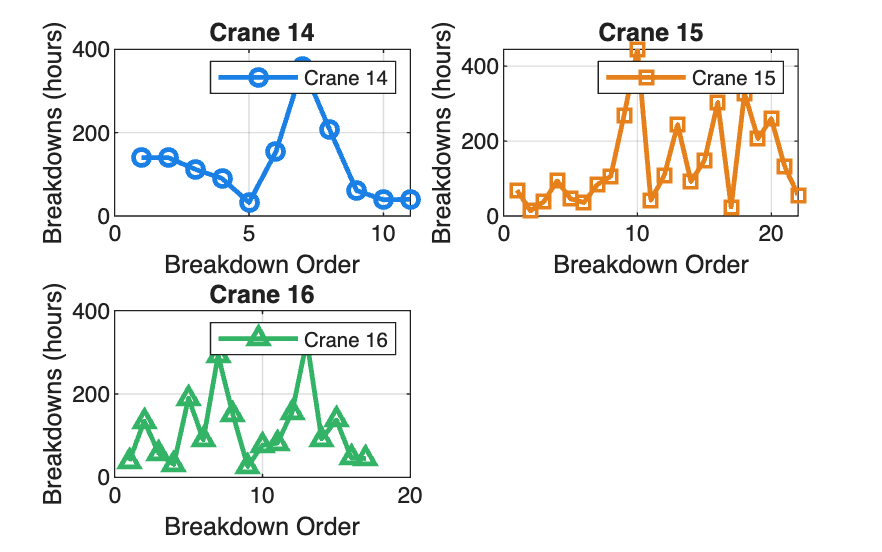

% === 创建每台起重机的故障序号 ===
orderA = 1:length(craneA);
orderB = 1:length(craneB);
orderC = 1:length(craneC);

% === 绘图 ===
figure('Color','w','Position',[200 200 800 500]);
hold on;
subplot(2,2,1);
plot(orderA, craneA, '-o', 'LineWidth', 1.8, 'Color', [0.1 0.5 0.9]);
xlabel('Breakdown Order');
ylabel('Breakdowns (hours)');
title('Crane 14');
legend('Crane 14', 'Location','northeast');
grid on;

subplot(2,2,2);
plot(orderB, craneB, '-s', 'LineWidth', 1.8, 'Color', [0.9 0.5 0.1]);
xlabel('Breakdown Order');
ylabel('Breakdowns (hours)');
title('Crane 15');
legend('Crane 15', 'Location','northeast');
grid on;

subplot(2,2,3);
plot(orderC, craneC, '-^', 'LineWidth', 1.8, 'Color', [0.2 0.7 0.4]);
xlabel('Breakdown Order');
ylabel('Breakdowns (hours)');
title('Crane 16');
legend('Crane 16', 'Location','northeast');
grid on;